clc;clear;
% load data
cry1 = imread("cry1.jpg");
cry2 = imread("cry2.jpg");
run1 = imread("run1.jpg");
run2 = imread("run2.jpg");

% convert to gray
cry1_gray = rgb2gray(cry1);
cry2_gray = rgb2gray(cry2);
run1_gray = rgb2gray(run1);
run2_gray = rgb2gray(run2);

% Calculate Gradients
[Ix1,Iy1,It1] = Gradients_Cal(cry1_gray,cry2_gray);
[Ix2,iy2,It2] = Gradients_Cal(run1_gray,run2_gray);

% Compute Optical Flow
[Vx1,Vy1] = OpticalFlow(Ix1,Iy1,It1);
[Vx2,Vy2] = OpticalFlow(Ix2,iy2,It2);

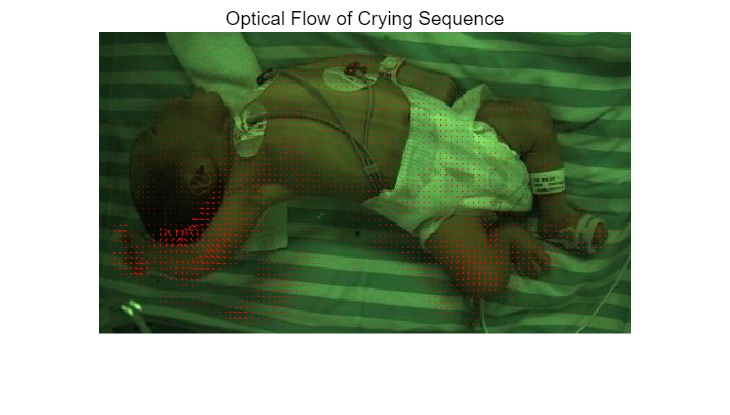

% Visualize Optical Flow
visualize_flow(Vx1,Vy1, cry1, 'Optical Flow of Crying Sequence')

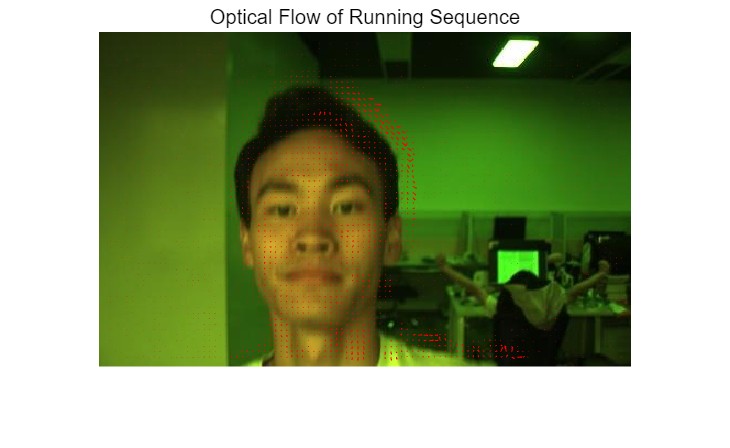

visualize_flow(Vx2,Vy2, run1, 'Optical Flow of Running Sequence')

function [Ix,Iy,It] = Gradients_Cal(img1,img2)
[Ix, Iy] = gradient(double(img1));
It = double(img2)-double(img1);
end
%
function [Vx,Vy] = OpticalFlow(Ix,Iy,It)
window_size = 15;
w = floor(window_size/2);
Vx = zeros(size(Ix));
Vy = zeros(size(Ix));
for i = 1+w:size(Ix,1)-w
        for j = 1+w:size(Ix,2)-w
            Ix_win = Ix(i-w:i+w, j-w:j+w);
            Iy_win = Iy(i-w:i+w, j-w:j+w);
            It_win = It(i-w:i+w, j-w:j+w);
            A = [Ix_win(:) Iy_win(:)];
            b = -It_win(:);
            v = pinv(A) * b;
            Vx(i,j) = v(1);
            Vy(i,j) = v(2);
        end
end
end
%
function visualize_flow(u, v, img, title_str)
% Display the original image
figure, imshow(img), hold on;
% Reduce the density of vectors for better visualization
skip = 5;
[X, Y] = meshgrid(1:skip:size(img, 2), 1:skip:size(img, 1));
u = u(1:skip:end, 1:skip:end);
v = v(1:skip:end, 1:skip:end);
% Plot the optical flow vectors
quiver(X, Y, u, v, 'r');
title(title_str);
hold off;
end